Addpath

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
addpath("..\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

## Configurations

Critical $t_s$ is $0.00789$ second.

SolverOpt

SolverOpt.initial_condition=config.StateInitial';
SolverOpt.end_time=config.SimulationTime;
SamplingTime=[0.002;0.0075;0.008];
% SolverOpt.sampling_time=config.ts;
SolverOpt.ratio=config.ratio;
SolverOpt.ode_setting=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

Other parameters

TargetAngle=config.TargetAngle';
Kp=diag(config.Kp);
Kd=diag(config.Kd);

Solver Option

option=odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

### Continuous Time Case

History Matrix

TorqueHistoryContinuous=zeros(7,round(SolverOpt.end_time/config.dt)+1);

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,PDTorque(Kp,Kd,State,TargetAngle)), ...
    0:config.dt:SolverOpt.end_time,SolverOpt.initial_condition,option);
command="data.continuous.duration=t;";
command=command+"data.continuous.state_history=State';";
eval(command);
for i=1:round(SolverOpt.end_time/config.dt)+1
    TorqueHistoryContinuous(:,i)=PDTorque(Kp,Kd,data.continuous.state_history(:,i),TargetAngle);
end
command="data.continuous.input_history=TorqueHistoryContinuous;";
eval(command);
toc

历时 3.855482 秒。


### Digital Feedback Control Case

System ODE and Input Function

SysODE=@(t,State,Torque)ODE(t,State,Torque);
InputFun=@(state)PDTorque(Kp,Kd,state,TargetAngle);

Simulation

for j=1:length(SamplingTime)
    SolverOpt.sampling_time=SamplingTime(j);
    sol=SampledControlSolver(SysODE,InputFun,SolverOpt);
    command="data.digital_"+num2str(j)+".ts="+num2str(SamplingTime(j))+";";
    command=command+"data.digital_"+num2str(j)+".duration=sol.duration;";
    command=command+"data.digital_"+num2str(j)+".state_history=sol.state_history;";
    command=command+"data.digital_"+num2str(j)+".input_history=sol.input_history;";
    eval(command);
end

历时 28.382202 秒。
历时 28.592928 秒。
历时 36.255461 秒。


MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

% Continous case
tic
data.continuous.EE_traj=panda.fkine(data.continuous.state_history(1:7,:)').transl';
toc

历时 68.054670 秒。


% Sampling system case
for j=1:length(SamplingTime)
    tic
    command="data.digital_"+num2str(j)+".EE_traj=panda.fkine(data.digital_"+...
        num2str(j)+".state_history(1:7,:)').transl';";
    eval(command);
    toc
end

历时 337.750525 秒。
历时 86.395708 秒。
历时 81.650496 秒。


Target of End Effector

EE_Target=panda.fkine(TargetAngle).transl';

Initial position of End Effector

EE_Initial=panda.fkine(SolverOpt.initial_condition(1:7)).transl';

End Effector Trajectory

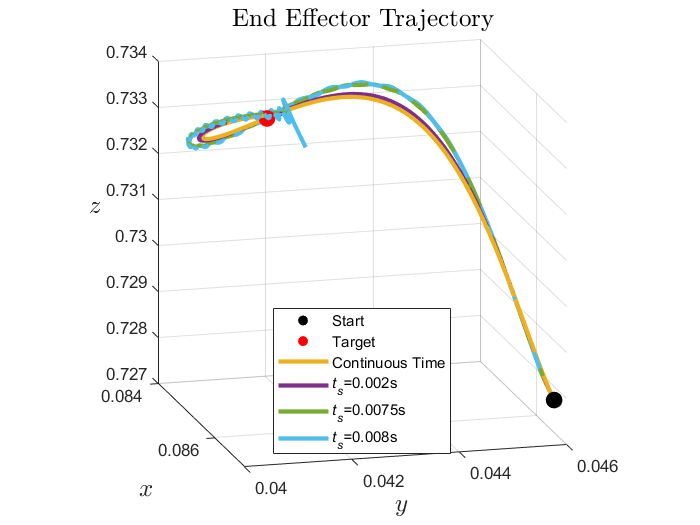

scatter3(EE_Initial(1),EE_Initial(2),EE_Initial(3),100,"black","filled","o")
hold on
scatter3(EE_Target(1),EE_Target(2),EE_Target(3),100,"red","filled","o")
plot3(data.continuous.EE_traj(1,:),data.continuous.EE_traj(2,:),...
    data.continuous.EE_traj(3,:),"LineWidth",2.5);
for j=1:length(SamplingTime)
    writting_data="data.digital_"+num2str(j)+".EE_traj";
    command="plot3("+writting_data+"(1,:),"+...
        writting_data+"(2,:),"+writting_data+...
        "(3,:),'LineWidth',2.5);";
    eval(command);
end
hold off
title("End Effector Trajectory", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
command="legend('Start','Target','Continuous Time',";
for j=1:length(SamplingTime)
    command=command+"'\itt_s=\rm"+num2str(SamplingTime(j))+"s',";
end
command=command+"'Location','south')";
eval(command);
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)

End Effector Error Visualization

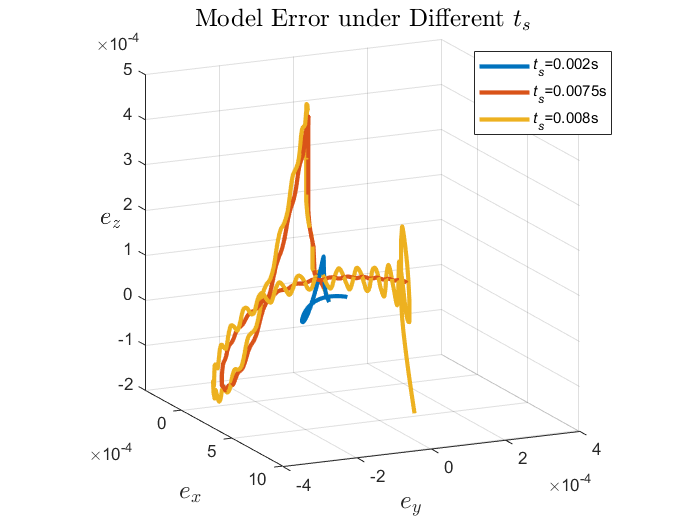

% 需要对齐采样频率
data.continuous.EE_traj_interp=data.continuous.EE_traj;
for j=1:length(SamplingTime)
    writting_data="data.digital_"+num2str(j);
    current_duration=writting_data+".duration";
    ideal_duration="data.continuous.duration";
    method="'spline'";
    command=writting_data+".EE_traj_interp=[";
    for i=1:3
        command=command+"interp1("+current_duration+","+writting_data+".EE_traj("+...
            num2str(i)+",:),"+ideal_duration+","+method+",'extrap')';";
    end
    command=command+"];";
    eval(command);
end

for j=1:length(SamplingTime)
    writting_data="data.digital_"+num2str(j)+".EE_traj_interp";
    command="plot3("+writting_data+"(1,:)-data.continuous.EE_traj_interp(1,:),"+...
        writting_data+"(2,:)-data.continuous.EE_traj_interp(2,:),"+writting_data+...
        "(3,:)-data.continuous.EE_traj_interp(3,:),'LineWidth',2.5);hold on";
    eval(command);
end
hold off
pbaspect([1 1 1])
xlabel("$$e_x$$","Interpreter","latex","FontSize",15)
ylabel("$$e_y$$","Interpreter","latex","FontSize",15)
zlabel("$$e_z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
command="legend(";
for j=1:length(SamplingTime)
    command=command+"'\itt_s=\rm"+num2str(SamplingTime(j))+"s',";
end
command=command+"'Location','best')";
eval(command);
title("Model Error under Different $$t_s$$", ...
    "FontSize",15,"Interpreter","latex")
view(65,15)
grid on

End Effector Error Time History

for j=1:length(SamplingTime)
    tic
    writting_data="data.digital_"+num2str(j)+".EE_traj_interp";
    command="data.digital_"+num2str(j)+".EE_error_history=data.continuous.duration;";
    for i=1:length(data.continuous.duration)
        command="data.digital_"+num2str(j)+".EE_error_history("+num2str(i)+")=norm("+...
            writting_data+"(:,i)-data.continuous.EE_traj_interp(:,i));";
        eval(command);
    end
    command="plot(data.continuous.duration,data.digital_"+num2str(j)+...
        ".EE_error_history,'LineWidth',2.5);hold on;";
    eval(command);
    toc
end

历时 44.254174 秒。
历时 44.507566 秒。
历时 44.437398 秒。


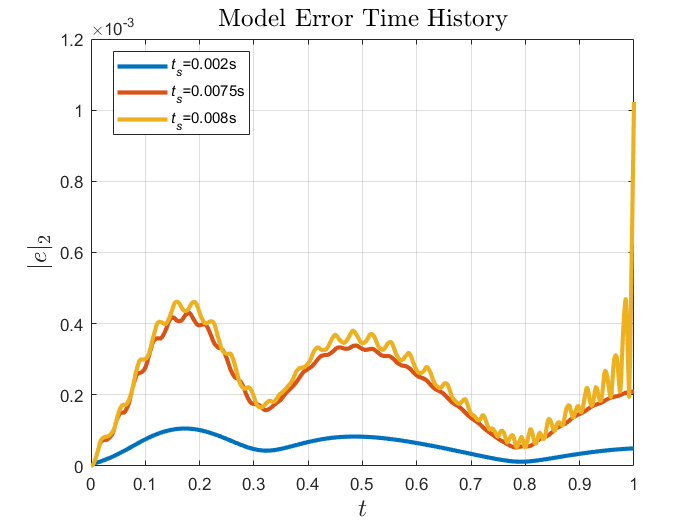

hold off
title("Model Error Time History","FontSize",15,"Interpreter","latex")
command="legend(";
for j=1:length(SamplingTime)
    command=command+"'\itt_s=\rm"+num2str(SamplingTime(j))+"s',";
end
command=command+"'Location','best')";
eval(command);
xlabel("$$t$$","Interpreter","latex","FontSize",15)
ylabel("$$|e|_2$$","Interpreter","latex","FontSize",15)
grid on

Save Data

filename="Data\Multi_ts_"+datestr(now,"yyyy_mm_dd")+".mat";
save(filename,'data')